
cd('E:\SEA pictures\190328\B1') 
p1 = imread('1.JPG');

light_org = imread('E:\SEA pictures\190308\light\l1.JPG');

p1 = im2double(p1); 

li = mat2gray(light_org); in_li = 1 - li;

p1 = immultiply(p1, in_li); 

% % small
% imshow(p1)
% h = imfreehand
% mask1 = createMask(h);
% 
% save mask1

% % big
% imshow(p1)
% h = imfreehand
% mask2 = createMask(h);
% 
% save mask2

% % big x 2
% imshow(p1)
% h = imfreehand
% mask3 = createMask(h);
% 
% save mask3

% % big x 3
% imshow(p1)
% h = imfreehand
% mask4 = createMask(h);
% 
% save mask4

% % big x 4
% imshow(p1)
% h = imfreehand
% mask5 = createMask(h);
% 
% save mask5

% % small + big
% imshow(p1)
% h = imfreehand
% mask6 = createMask(h);
% 
% save mask6

% % small + big x 2
% imshow(p1)
% h = imfreehand
% mask7 = createMask(h);
% 
% save mask7

% % small + big x 3
% imshow(p1)
% h = imfreehand
% mask8 = createMask(h);
% 
% save mask8

% % small + big x 4
% imshow(p1)
% h = imfreehand
% mask9 = createMask(h);
% 
% save mask9

load('mask1')
load('mask2')
load('mask3')
load('mask4')
load('mask5')
load('mask6')
load('mask7')
load('mask8')
load('mask9')

p1M = p1.*mask1; p2M = p1.*mask2; p3M = p1.*mask3; p4M = p1.*mask4; p5M = p1.*mask5;
p6M = p1.*mask6; p7M = p1.*mask7; p8M = p1.*mask8; p9M = p1.*mask9;

A1g = rgb2gray(p1M); A2g = rgb2gray(p2M); A3g = rgb2gray(p3M);
A4g = rgb2gray(p4M); A5g = rgb2gray(p5M); A6g = rgb2gray(p6M); A7g = rgb2gray(p7M);
A8g = rgb2gray(p8M); A9g = rgb2gray(p9M); 

th = 0.1176;
A1bw = (A1g > th); A2bw = (A2g > th); A3bw = (A3g > th); 
A4bw = (A4g > th); A5bw = (A5g > th); A6bw = (A6g > th); A7bw = (A7g > th); 
A8bw = (A8g > th); A9bw = (A9g > th);

A1a = sum(A1bw(:)); A2a = sum(A2bw(:)); A3a = sum(A3bw(:)); 
A4a = sum(A4bw(:)); A5a = sum(A5bw(:)); A6a = sum(A6bw(:)); A7a = sum(A7bw(:));
A8a = sum(A8bw(:)); A9a = sum(A9bw(:));

AaM =  [0 A1a, A2a, A6a, A3a, A7a, A4a, A8a, A5a, A9a];
area = [0 13.2 52.8 66 105.6 118.8 158.4 171.6 211.2 224.4];
pixels = AaM;

pixels = pixels';
area = area';

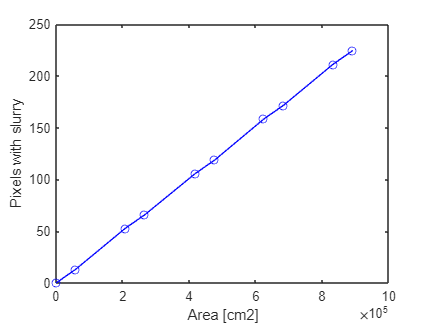

plot(pixels, area, 'b-o')
xlabel('Area [cm2]')
ylabel('Pixels with slurry')

fit_type = 'poly1'

fit_type = 'poly1'


[fit1, gof, output] = fit(pixels, area, fit_type)

fit1 =      Linear model Poly1:
     fit1(x) = p1*x + p2
     Coefficients (with 95% confidence bounds):
       p1 =   0.0002534  (0.0002509, 0.0002559)
       p2 =     -0.8415  (-2.179, 0.4957)

gof = struct with fields:
           sse: 8.2166
       rsquare: 0.9999
           dfe: 8
    adjrsquare: 0.9998
          rmse: 1.0134


output = struct with fields:
        numobs: 10
      numparam: 2
     residuals: [10×1 double]
      Jacobian: [10×2 double]
      exitflag: 1
     algorithm: 'QR factorization and solve'
    iterations: 1


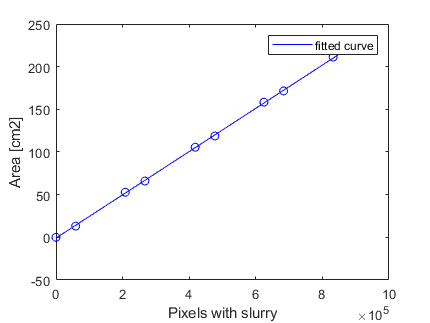


plot(pixels, area, 'b o')
hold on
plot(fit1, 'b')
hold off
ylabel('Area [cm2]')
xlabel('Pixels with slurry')

% equation: 
% area [cm2] = 0.00025162 * pixels 

slope = pixels(:)\area(:)

slope = 2.5212e-04